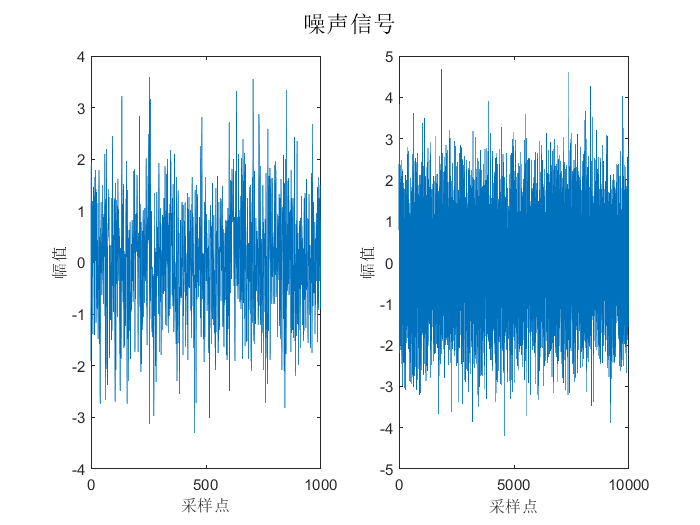

clc;clear all;
close all;
%产生长度为1000和10000的白噪声
len1=1000;
len2=10000;
row=1;%生成噪声矩阵的列数
power=1;%生成噪声的功率，dBW
w1=wgn(row,len1,power,'real');
w2=wgn(row,len2,power,'real');
figure(1);
sgtitle("噪声信号")
subplot(121);plot(0:len1-1,w1);xlabel("采样点");ylabel("幅值")
subplot(122);plot(0:len2-1,w2);xlabel("采样点");ylabel("幅值")

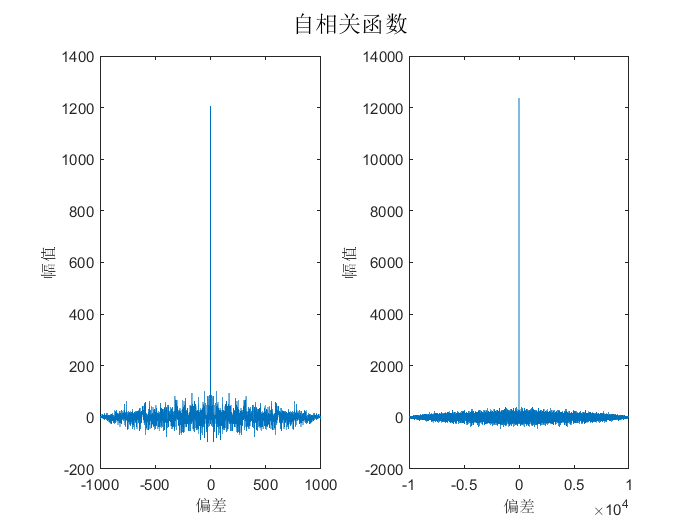

%求噪声的自相关函数
r1=xcorr(w1,w1);
r2=xcorr(w2,w2);
figure(3);
sgtitle("自相关函数")
subplot(121);plot(1-len1:len1-1,r1);xlabel("偏差");ylabel("幅值")
subplot(122);plot(1-len2:len2-1,r2);xlabel("偏差");ylabel("幅值")